## Formulation

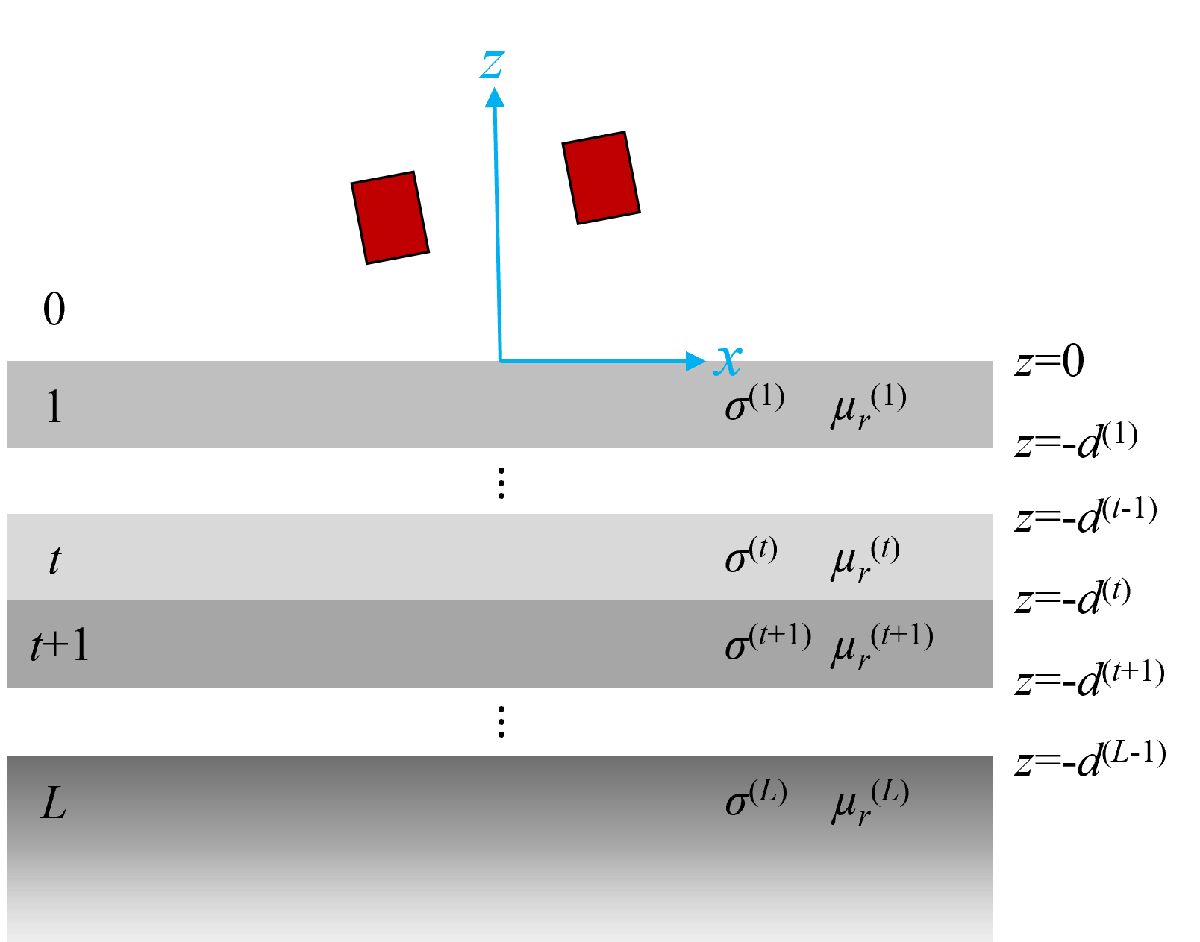

The governing equation for the eddy current problem with Columb gauge $\nabla \cdot \mathbf{A}=0$ is

$\nabla^2 \mathbf{A}=k^2 \mathbf{A}$   where   $k^2 =j\omega \mu_0 \mu_r \sigma$

Choosing a second order potential

$\mathbf{W}=W_a {\mathbf{e}}_z +{\mathbf{e}}_z \times \nabla W_b$   and   $\mathbf{A}=\nabla \times \mathbf{W}$

results in the Helmholtz equation for $W_a$ and $W_b$


$$\frac{\partial^2 W_{a,b} }{\partial x^2 }+\frac{\partial^2 W_{a,b} }{\partial y^2 }+\frac{\partial^2 W_{a,b} }{\partial z^2 }=k^2 W_{a,b}$$


However, since the z component of the electric field inside the conductive layer is zero $0E_z^{\left(0\right)} =\sigma^{\left(1\right)} E_z^{\left(1\right)}$ and $A_z =-\frac{\partial^2 W_b }{\partial x^2 }-\frac{\partial^2 W_b }{\partial y^2 }$, $W_b$ should be zero for the conductive layers.

Additionally, the magnetic flux density is


$$\begin{array}{l}
B_x =\;\;\;k^2 \frac{\partial W_b }{\partial y}+\frac{\partial^2 W_a }{\partial x\partial z}\\
B_y ={-k}^2 \frac{\partial W_b }{\partial x}+\frac{\partial^2 W_a }{\partial y\partial z}\\
B_z ={-k}^2 W_a +\frac{\partial^2 W_a }{\partial z^2 }
\end{array}$$


Since $k=0$ in the air region, $W_b$ does not contribute to the magnetic flux density. Thus, $W_b$ can also be set zero for in the air region. Since only $W_a$ is left, we will refer to $W_a$ as simply $W$.

Taking the Fourier transform in the x and y direction


$$\tilde{W} \left(u,v,z\right)=\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } W\left(x,y,z\right)e^{-jux} e^{-jvy} dxdy$$


The governing equation becomes

$\frac{\partial^2 \tilde{W} }{\partial z^2 }=\lambda^2 \tilde{W}$   where   $\lambda^2 =k^2 +\kappa^2$ and $\kappa^2 =u^2 +v^2$

$W$ in the air region and in the layers *t*=1~*L* thus have the form


$$W^{\left(0\right)} =C^{\left(s\right)} e^{\kappa z} +D^{\left(\mathrm{ec}\right)} e^{-\kappa z}$$



$$W^{\left(t\right)} =C^{\left(t\right)} e^{\lambda^{\left(t\right)} z} +D^{\left(t\right)} e^{-\lambda^{\left(t\right)} z}$$


The $C^{\left(s\right)} e^{\kappa z}$ term is due to the coil source, and the $D^{\left(\textrm{ec}\right)} e^{-\kappa z}$ term is due to eddy current. Additionally, $D^{\left(L\right)} =0$ since layer $L$ extends to $z=-\infty$.

Other fields can be derived from


$$\begin{array}{l}
{\tilde{A} }_x \left(u,v,z\right)=jv\tilde{W} \left(u,v,z\right)\\
{\tilde{A} }_y \left(u,v,z\right)=-ju\tilde{W} \left(u,v,z\right)\\
{\tilde{A} }_z \left(u,v,z\right)=0
\end{array}$$


 
$$\begin{array}{l}
{\tilde{B} }_x \left(u,v,z\right)=ju\frac{\partial \tilde{W} \left(u,v,z\right)}{\partial z}\\
{\tilde{B} }_y \left(u,v,z\right)=jv\frac{\partial \tilde{W} \left(u,v,z\right)}{\partial z}\\
{\tilde{B} }_z \left(u,v,z\right)=-k^2 \tilde{W} \left(u,v,z\right)+\frac{\partial^2 \tilde{W} \left(u,v,z\right)}{\partial z^2 }
\end{array}$$


and recovered using the inverse Fourier transform


$$F\left(x,y,z\right)=\frac{1}{4\pi^2 }\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } \tilde{F} \left(u,v,z\right)e^{jux} e^{jvy} dudv$$


### Source term

#### Filamentary coil

TODO

#### Cylindrical coil

TODO

#### Magnetic sensor

For a magnetic sensor located at $\left(x_0 ,y_0 ,z_0 \right)$ and senses magnetic flux density component to $\left(t_x ,t_y ,t_z \right)$, the coefficient $C^{\left(s\right)}$ is given by


$$C^{\left(s\right)} =-\frac{\mu_0 }{2\omega }\frac{1}{\kappa^2 }\left({ut}_x +{vt}_y -j\kappa t_z \right)e^{-j{ux}_0 -j{vy}_0 -\kappa z_0 }$$


### Computation of coefficients

The interface conditions between layer *t* and layer *t*+1 are


$${\left\lbrack \begin{array}{c}
B_z^{\left(t\right)} =B_z^{\left(t+1\right)} \\
\frac{1}{\mu_r^{\left(t\right)} }B_{x,y}^{\left(t\right)} =\frac{1}{\mu_r^{\left(t+1\right)} }B_{x,y}^{\left(t+1\right)} 
\end{array}\right\rbrack }_{z=-d^{\left(t\right)} }$$


Which leads to the following matrix equation


$$\left\lbrack \begin{array}{c}
C^{\left(t\right)} \\
D^{\left(t\right)} 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cc}
e^{\left(-\lambda^{\left(t+1\right)} +\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1+\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right) & e^{\left(\lambda^{\left(t+1\right)} +\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1-\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right)\\
e^{\left(-\lambda^{\left(t+1\right)} -\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1-\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right) & e^{\left(\lambda^{\left(t+1\right)} -\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1+\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C^{\left(t+1\right)} \\
D^{\left(t+1\right)} 
\end{array}\right\rbrack$$


Starting from layer *L*-1 and going up iteratively, the coefficient of any layer can be related to the coefficient of layer *L*.


$$\left\lbrack \begin{array}{c}
C^{\left(t\right)} \\
D^{\left(t\right)} 
\end{array}\right\rbrack ={\mathbf{V}}^{\left(t\right)} \left\lbrack \begin{array}{c}
C^{\left(L\right)} \\
0
\end{array}\right\rbrack$$


And by applying the interface conditions between layer 1 and the air region, we obtain


$$C^{\left(L\right)} =\frac{2\kappa \mu_r^{\left(1\right)} }{\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }C^{\left(s\right)}$$



$$D^{\left(\textrm{ec}\right)} =\frac{\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }{\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }C^{\left(s\right)}$$


## Function

### Usage

Initiate a coil above plate in Cartesian coordinates model. `width/2` is the maximum x and y coordinate to evaluate at.

Evaluate field at position `(x,y,z)`. The result is correct only if `z` is lower than all coils.` fieldname` could be `'Ax'` `'Ay'` `'Az'` `'Ex'` `'Jx'` `'Bx'` `'Hx' ...`

### Coils

If there is a single coil, `coils` is a *structure array.* If there are more than one coil, `coils` is a *cell array.*

Coil could be of type filamentary, cylindrical, or a magnetic sensor.

### Layers

`layers` is a *cell array*

Specify the electrical conductivity, relative magnetic permeability, and thickness of each layer. The last layer must have infinite thicknes.

function Model = CoilAbovePlate3D(coils, layers, varargin)

if ~iscell(coils)
    coils = {coils};
end

for t = 1:numel(layers)
    assert(layers{t}.sigma >= 0);
    assert(layers{t}.mur >= 1);
    assert(layers{t}.thickness > 0);
end
assert(layers{end}.thickness == Inf)

p = inputParser;
addParameter(p, 'TruncateWidth', 0.1); % (m)
addParameter(p, 'SummationTerms', 500);
parse(p, varargin{:});

N = floor(p.Results.SummationTerms / 2);
delta_x = p.Results.TruncateWidth / 2 / N;
delta_u = 2*pi / delta_x / (2*N+1);
[u,v] = ndgrid((-N:N) * delta_u, (-N:N) * delta_u);
kappa = sqrt(u.^2 + v.^2);
% avoid division by zero
mask = kappa == 0;
epsilon = delta_u * 1e-10;
u(mask)     = epsilon;
v(mask)     = epsilon;
kappa(mask) = epsilon * sqrt(2);

Model.coils = coils;
Model.layers = layers;
Model.impl = struct('N',N, 'delta_x',delta_x, 'u',u, 'v',v, 'kappa',kappa);

Model.EvaluateField = @(fieldnames, x,y,z, omega) EvaluateField(Model, fieldnames, x,y,z, omega);

end

function varargout = EvaluateField(Model, fieldnames, x, y, z, omega)

if ~iscell(fieldnames)
    fieldnames = {fieldnames};
end
varargout = cell(1, numel(fieldnames));

u     = Model.impl.u;
v     = Model.impl.v;
kappa = Model.impl.kappa;
L     = numel(Model.layers);

Cs  = Cs_func(Model.coils, u, v, kappa, omega);
Dec = zeros([size(kappa) 1]);
Ct  = zeros([size(kappa) L]);
Dt  = zeros([size(kappa) L]);
for i = 1:size(kappa,1)
for j = 1:size(kappa,2)
    [Dec(i,j), Ct(i,j,:), Dt(i,j,:)] = CoilAbovePlateCoefficients(Model.layers, kappa(i,j), omega, Cs(i,j));
end
end

for p = 1:numel(fieldnames)
    varargout{p} = zeros(size(x));
    for z_layer = reshape(unique(z), 1,[])
        mask = z == z_layer;
        varargout{p}(mask) = EvaluateField_single_z(Model, fieldnames{p}, Cs, Dec, Ct, Dt, x(mask), y(mask), z_layer, omega);
    end
end

end

function field = EvaluateField_single_z(Model, fieldname, Cs, Dec, Ct, Dt, x,y,z, omega)

assert(isscalar(z))
mu0 = 4*pi * 1e-7;

N       = Model.impl.N;
delta_x = Model.impl.delta_x;
u       = Model.impl.u;
v       = Model.impl.v;
kappa   = Model.impl.kappa;

diff_z = false;
if strcmp(fieldname,'Bx') || strcmp(fieldname,'By') || strcmp(fieldname,'Hx') || strcmp(fieldname,'Hy') 
    diff_z = true;
end

idx = FindLayer(Model.layers, z);
if idx == 0
    sigma = 0;
    mur = 1;

    if ~diff_z
        W =     Cs .* exp(kappa * z) + Dec .* exp(-kappa * z);
    else
        dWdz = (Cs .* exp(kappa * z) - Dec .* exp(-kappa * z)) .* kappa;
    end
else
    sigma = Model.layers{idx}.sigma;
    mur   = Model.layers{idx}.mur;

    Ct = Ct(:,:,idx);
    Dt = Dt(:,:,idx);
    lambda = sqrt(kappa.^2 + 1j * omega * mu0 * mur * sigma);
    if ~diff_z
        W =     Ct .* exp(lambda * z) + Dt .* exp(-lambda * z);
    else
        dWdz = (Ct .* exp(lambda * z) - Dt .* exp(-lambda * z)) .* lambda;
    end
end

fieldname = char(fieldname);
assert(length(fieldname) == 2)

if fieldname(1) == 'A' || fieldname(1) == 'E' || fieldname(1) == 'J'
    switch fieldname(2)
        case 'x'
            fft_field =  1j * v .* W;
        case 'y'
            fft_field = -1j * u .* W;
        case 'z'
            fft_field = zeros(size(kappa));        
        otherwise
            error('Unknown field name "%s"', fieldname)
    end
    if fieldname(1) == 'E'
        fft_field = fft_field * (-1j * omega);
    elseif fieldname(1) == 'J'
        fft_field = fft_field * (-1j * omega * sigma);
    end
elseif fieldname(1) == 'B' || fieldname(1) == 'H'
    switch fieldname(2)
        case 'x'
            fft_field =  1j * u .* dWdz;
        case 'y'
            fft_field =  1j * v .* dWdz;
        case 'z'
            fft_field = kappa.^2 .* W;       
        otherwise
            error('Unknown field name "%s"', fieldname)
    end
    if fieldname(1) == 'H'
        fft_field = fft_field / (mu0 * mur);
    end
else
    error('Unknown field name "%s"', fieldname)
end

fft_field = ifftshift(fft_field);
field = ifft2(fft_field) / delta_x^2; 
field = fftshift(field);

[xs,ys] = ndgrid((-N:N) * delta_x, (-N:N) * delta_x);
field = interpn(xs,ys,field, x,y);

end

function val = Cs_func(coils, u, v, kappa, omega)

mu0 = 4*pi * 1e-7;

val = 0;
for p = 1:numel(coils)
    coil = coils{p};
    switch lower(coil.type)
        case 'magneticsensor'
            x0 = coil.position(1);
            y0 = coil.position(2);
            z0 = coil.position(3);
            tx = coil.sense_axis(1);
            ty = coil.sense_axis(2);
            tz = coil.sense_axis(3);
            val = -mu0/2 / omega ./ kappa.^2 .* (u*tx + v*ty - 1j*kappa*tz) .* exp(-1j*u*x0 - 1j*v*y0 - kappa*z0);

        otherwise
            error('Unknown coil type "%s"', coils{p}.type)
    end
end

end

function idx = FindLayer(layers, z)
if z > 0
    idx = 0;
    return
end
bottom_z = 0;
for idx = 1:numel(layers)
    bottom_z = bottom_z - layers{idx}.thickness;
    if z >= bottom_z
        return
    end
end
end